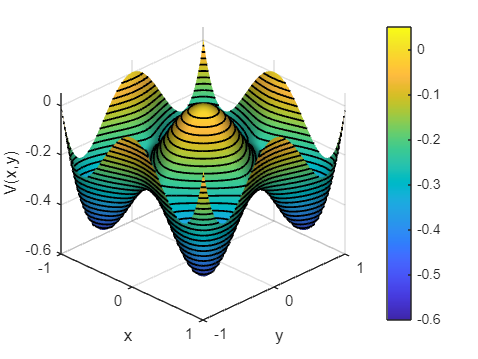

% Potential parameters
alpha = 1;
beta  = 0;
delta = 0;

% Grid on [-1,1] × [-1,1]
N = 400;
x = linspace(-1, 1, N);
y = linspace(-1, 1, N);
[X, Y] = meshgrid(x, y);

% Compute the potential
V = X.^4 - alpha.*X.^2 - delta.*X + Y.^4 - Y.^2 + beta.*X.^2.*Y.^2;

% Main 3D surface
surf(X, Y, V, 'FaceAlpha', 1.0, 'EdgeColor', 'none');
colormap(parula);
shading interp;
hold on;

% Contour lines on the surface and its base shadow
contour3(X, Y, V, 20, 'k', 'LineWidth', 1.2);

% Axes and view
xlabel('x'); ylabel('y'); zlabel('V(x,y)');
axis([-1 1 -1 1 -0.6 0.05]);
view(45,30);
grid on;

% Lighting and surface appearance
material dull;
lighting gouraud;
camlight headlight;
caxis([-0.6, 0.05]);
colorbar;
hold off;

colorbar;

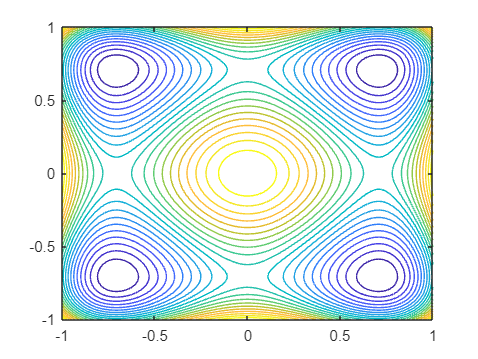

Unrecognized function or variable 's'.


% Contour plot with white background and colored lines
figure('Name','Contour Plot','NumberTitle','off')
set(gcf, 'Color', 'w'); 
[~, h] = contour(X, Y, V, 20); 
colormap(parula);

h.LineWidth = 1.2; 
colorbar;
caxis([-0.6, 0.05]);
axis equal; axis([-1 1 -1 1]);
xlabel('x'); ylabel('y');
box on;

